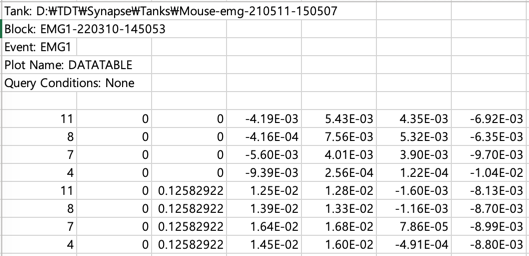

reader = channelReader();

tic 
%                            
reader.readMultiChannelFile( ...
    "./data/height1 - 1,10s - 2x.xlsx", ...#filename
    1, ...#channelColumnIdx
    3, ...#timeColumnIdx
    7, ...#startRowIdx
    4, ...#startColIdx
    nan ... #sample frequency. time column이 있으면 자동으로 frequency 계산하므로 nan을 입력
    ); %일단 파일을 불러옴
toc % 코드 실행 시간 측정. 오래 걸림.
%                            organoid, channel, month 


#### enveloping smoothing 추가

#### 1. preview of processing on single channel 

emg = reader.readSingleChannelFromFile(1, 8, 1);

channel number = 8
sampling rate = 1017.252602Hz
starts at 0.000000, ends at 54.859530, duration = 54.859530
number of timestamps = 55807



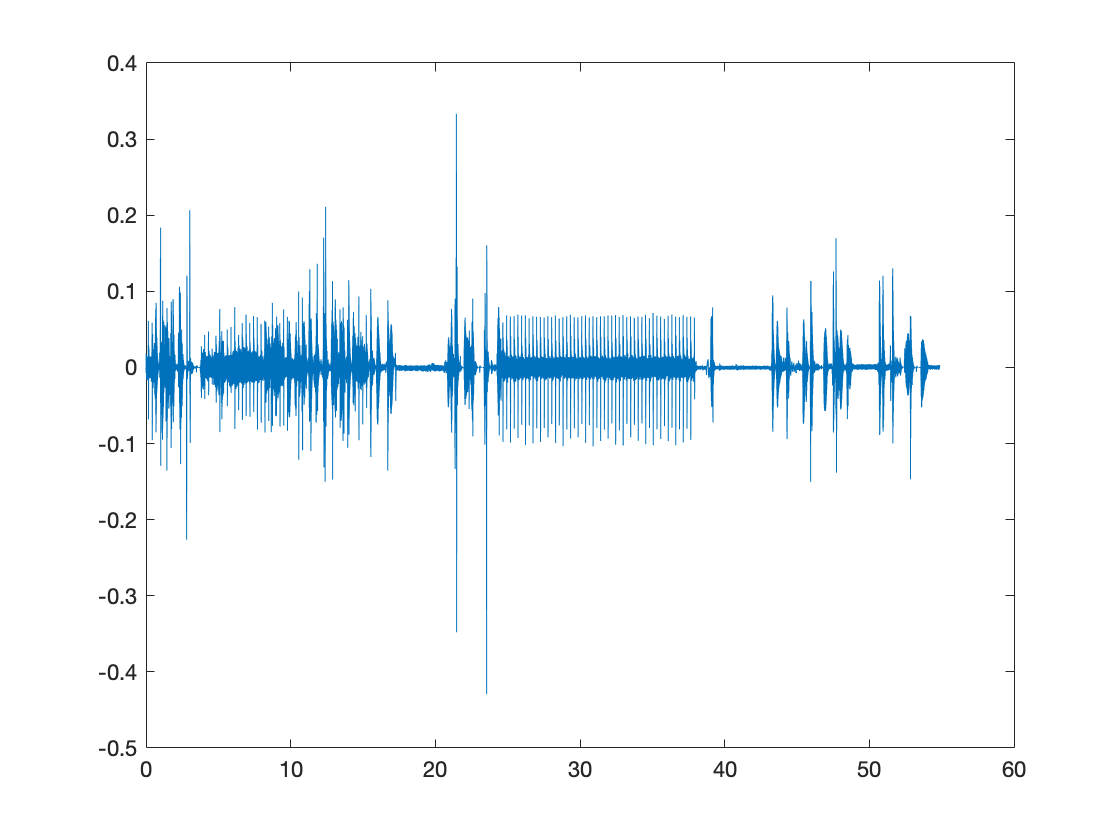

emg.highPassButterworth(3, 30) % 3rd order Butterworth high pass filter at 30 Hz
emg.notchButterworth(3, [49,51]) % 5th order Butterworth notch filter to reduce the noise at 50 Hz.

% compare
figure;
plot(emg.t, emg.raw);

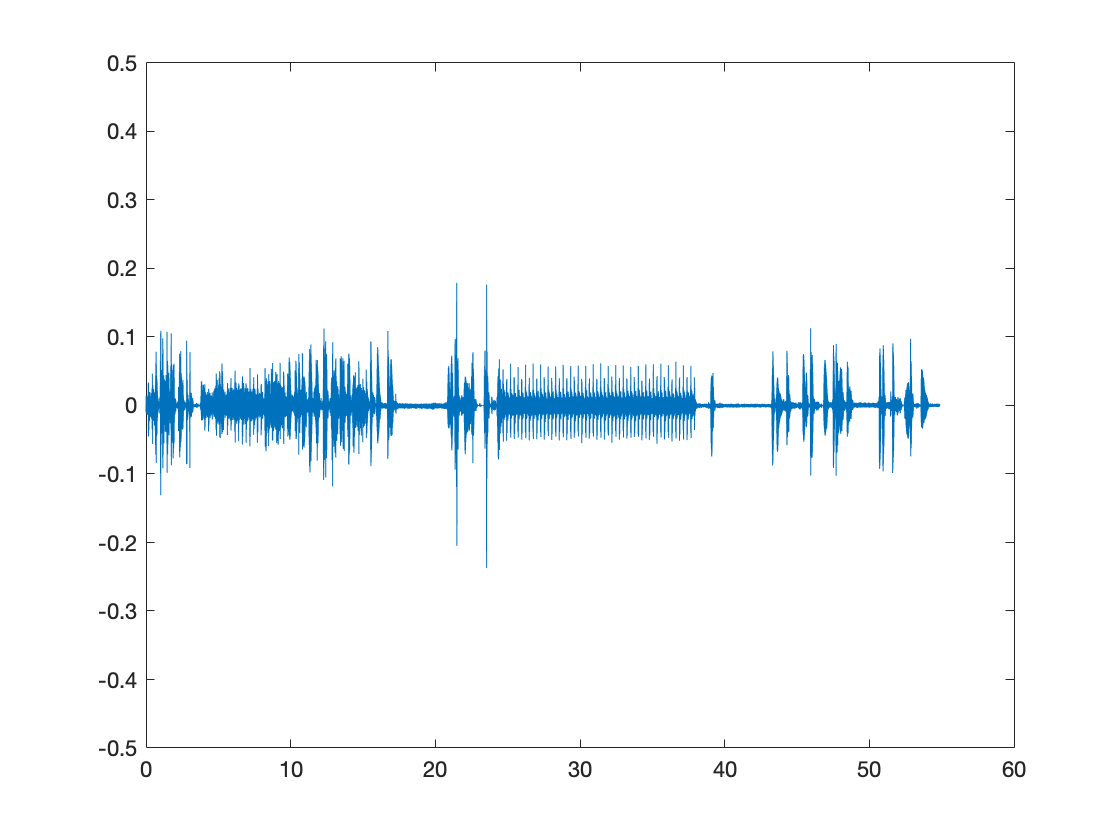

plot(emg.t, emg.filtered);
ylim([-0.5 0.5])

emg.cutTime([25,40]);

new startTime = 24.999690
new endTime = 40.000881
new duration = 15.001190
new nTimestamp = 15261


fgfgfg

fgfg

emg.rectify();

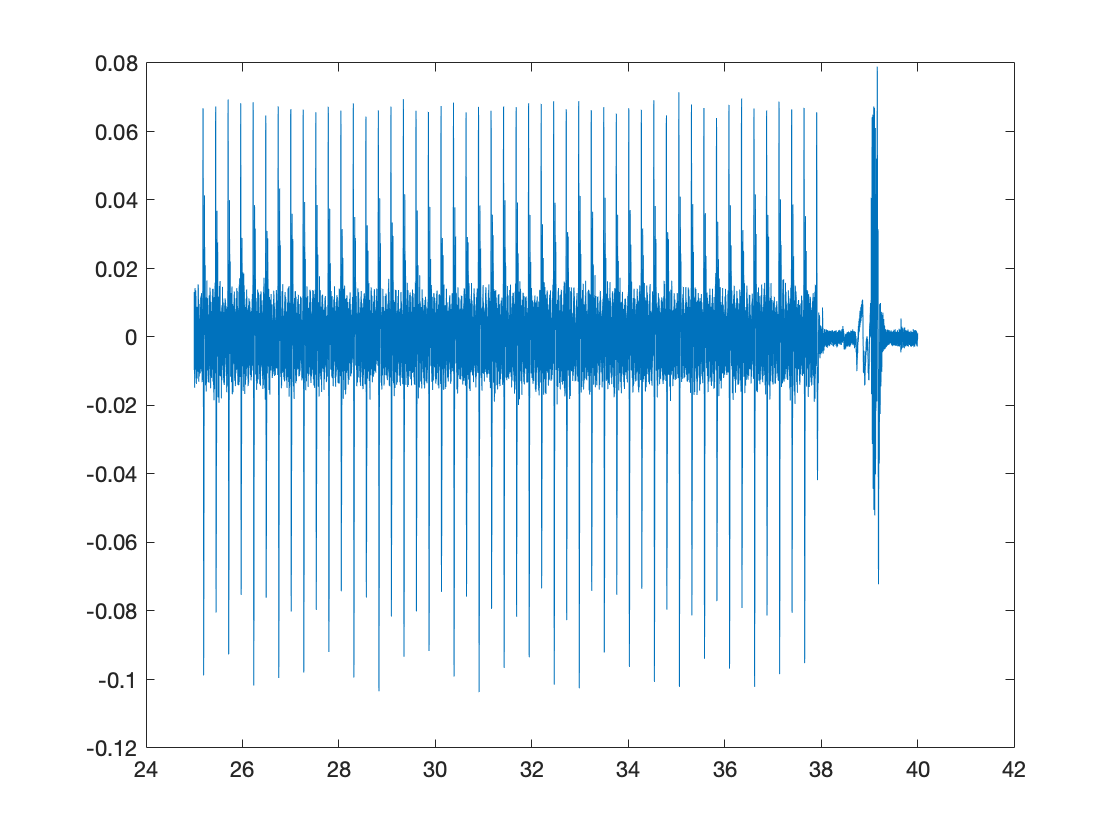

plot(emg.t, emg.raw)

emg.envelope(1000)
plot(emg.t, emg.signalRawRectified)

다음 사용 중 오류가 발생함: plot
벡터들의 길이는 같아야 합니다.

plot(emg.t, emg.signalFilteredRectified)

dfdf

matlab signal processing toolbox 설치 필요

Computes the RMS-envelope, the MA-envelope ot the LE-envelope of an EMG signal.

emg.envelope(4000);
plot(emg.t, emg.signalRawEnveloped)

다음 사용 중 오류가 발생함: plot
벡터들의 길이는 같아야 합니다.

plot(emg.t, emg.signalFilteredEnveloped)

length(emg.signalFilteredEnveloped)

%                                 organoid, month
pixels = reader.readManyChannelsFromFile(1, 1);
pixels.keys

sampling rate가 모두 똑같은 상황을 가정하고 코드를 짰음


%                      nrow, ncol
ani = timeVaryingHeatmapEMG(2,2); % timeVaryingHeatmap 오브젝트 생성. pixel들이 2*2 배열로 되어 있다고 가정.

%  이 pixel의 row번호, column번호, pixel에 mapping할 channel 번호
ani.addPixel(1, 1, pixels(4) );


 In the (1, 1)th slot, added channel 4 


ani.addPixel(1, 2, pixels(7) );


 In the (1, 2)th slot, added channel 7 


ani.addPixel(2, 1, pixels(8) );


 In the (2, 1)th slot, added channel 8 


ani.addPixel(2, 2, pixels(11));


 In the (2, 2)th slot, added channel 11 


step size = 102 timestamps = 100.270080 miliseconds
Total 99 steps
max signal value = 0.063186, ColorLimits is set w.r.t this value.

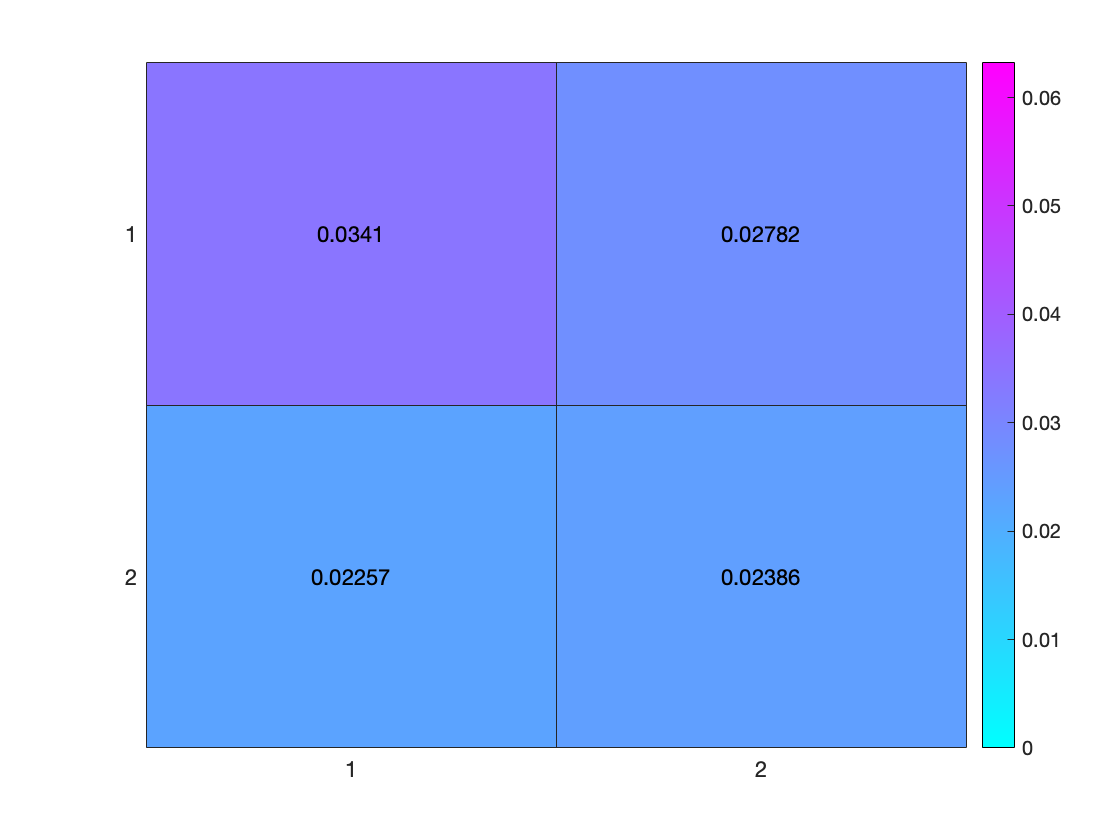

ani.highPassButterworth(3, 30) % 3rd order Butterworth high pass filter at 30 Hz
ani.notchButterworth(3, [49,51]) % 5th order Butterworth notch filter to reduce the noise at 50 Hz.
ani.rectify()      % 모든 channel에 일괄적으로 rectification 적용
ani.envelope(500) % 모든 channel에 일괄적으로 rms enveloping 적용 
%ani.normalizeEnvelope(0.3) % 모든 channel에 일괄적으로 enveloped signal의 max가 0.3이 되도록 normalize

%                           
ani.makeTimeVaryingHeatmap( ...
    100, ... % 시간 간격(millisecond)
    true, ... % filterd or not
    cool) %colormap

step size = 1017 timestamps = 999.751682 miliseconds
Total 10 steps
max signal value = 0.062012, ColorLimits is set w.r.t this value.

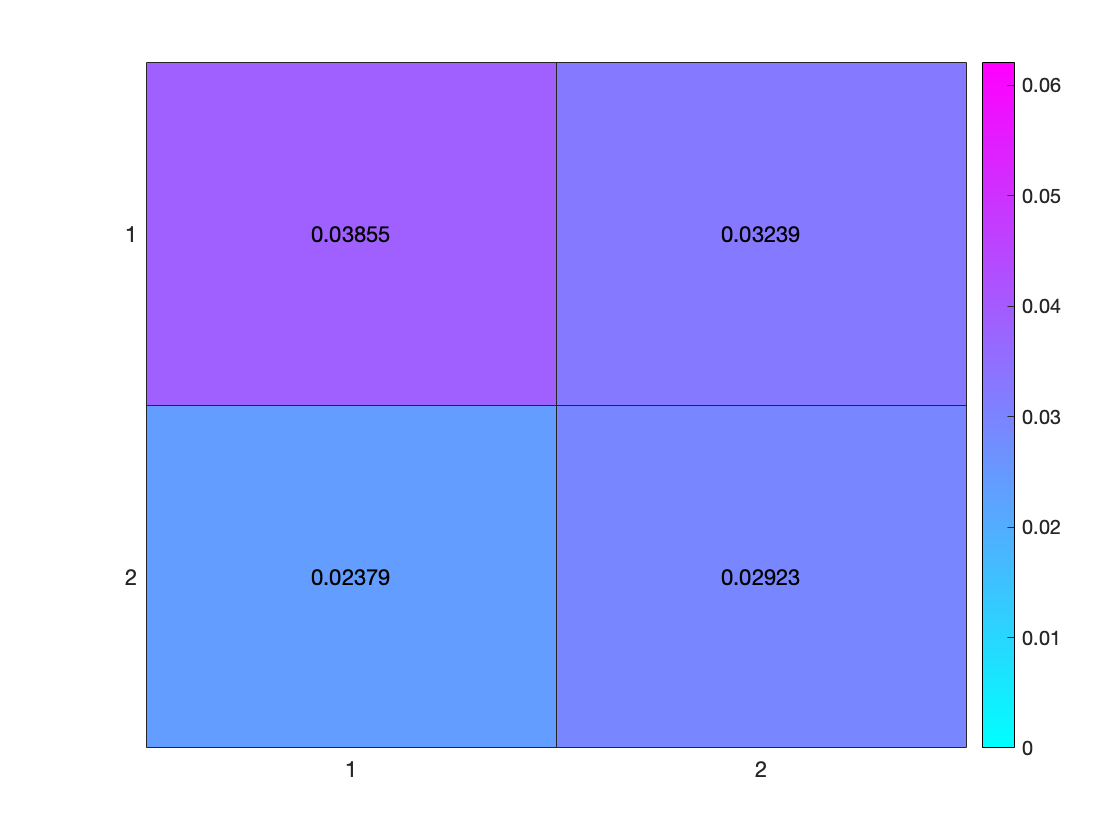

- 시간 커팅

- 값들만 나오면 됨

- 데이터 포맷 한줄

- 필터링 선택 스위치

plot을 위해서 main이 아닌 부위는 폭을 줄이ㄷ기

plot 에서 데이터 테이블로 뺴기

SNR standard한 공식 log ....

time interval을 milisecond 단위로 입력ㅅ

true